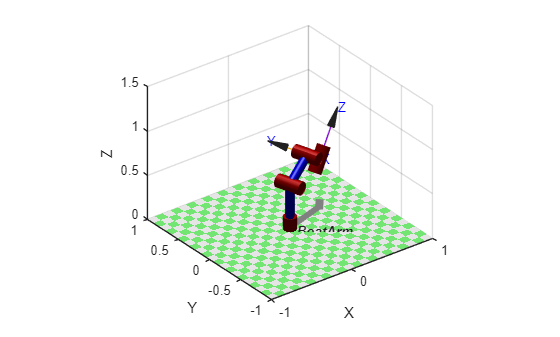

clear; clc; close all;



% DH-parameters (standard)
L1 = Link([0      0.50   0       pi/2], 'standard');   
L2 = Link([0      0      0.35    0   ], 'standard');   
L3 = Link([0      0      0.25   -pi/2], 'standard');  
L4 = Link([0      0      0.20    0   ], 'standard');   

MarineArm = SerialLink([L1 L2 L3 L4], 'name', 'BoatArm');

%(alle vinkler = 0)
q_straight = [0 0 0 0];
T_straight = MarineArm.fkine(q_straight);

%(foldet arm)
q_drive = [pi/2  -pi/3   pi/4   0];
T_drive = MarineArm.fkine(q_drive);

%(en fin pose ute i rommet)
q_work = [0.3   0.6   -1.2   0.5];
T_work = MarineArm.fkine(q_work);

%% INVERSE KINEMATIKK til samme posisjon som q_work
% 4 DOF → kan ikke styre full orientasjon, bare posisjon
mask = [1 1 1 0 0 0];   % x, y, z aktiv

qi = MarineArm.ikine(T_work, 'mask', mask);

%% JACOBIAN i arbeidsposisjon
J = MarineArm.jacob0(q_work);

% Eksempel på leddhastigheter og tilsvarende EE-hastighet
joint_vel = [0.1; 0.1; -0.1; 0.2];   % 4×1
eef_vel   = J * joint_vel;           % 6×1 (vx, vy, vz, wx, wy, wz)

%% PLOT – KUN ÉN POSISJON (ingen bevegelse / animasjon)
ws = [-1 1 -1 1 0 1.5];   % workspace: [xmin xmax ymin ymax zmin zmax]

% Velg hvilken du vil se: q_straight, q_drive, q_work eller qi
q_show = q_work;   % endre her hvis du vil se en annen posisjon

MarineArm.plot(q_show, 'workspace', ws);